
d = 1

d = 1

i = 1

i = 1


nSess = 2

nSess = 2


for n = 1:nSess
    
    loBehState_NthDthCRFSess = loBehState_allSessAllPtsAllDurs_CRF(d,:,i,n);

    % max of dth ith CRF
    clear maxOfCRF
    maxOfCRF = max(loBehState_NthDthCRFSess);

    % scale the CRF to it's max
    scaled_loBehState_NthDthCRFSess = loBehState_NthDthCRFSess/maxOfCRF;

    % COLLLECT scaled CRF for each session (to get st err later)
    allSess_scaled_loBehState_CRF(n,:) = scaled_loBehState_NthDthCRFSess;
    
end 

size(allSess_scaled_loBehState_CRF)

Error using error
The message must be specified as either a string or a message structure.


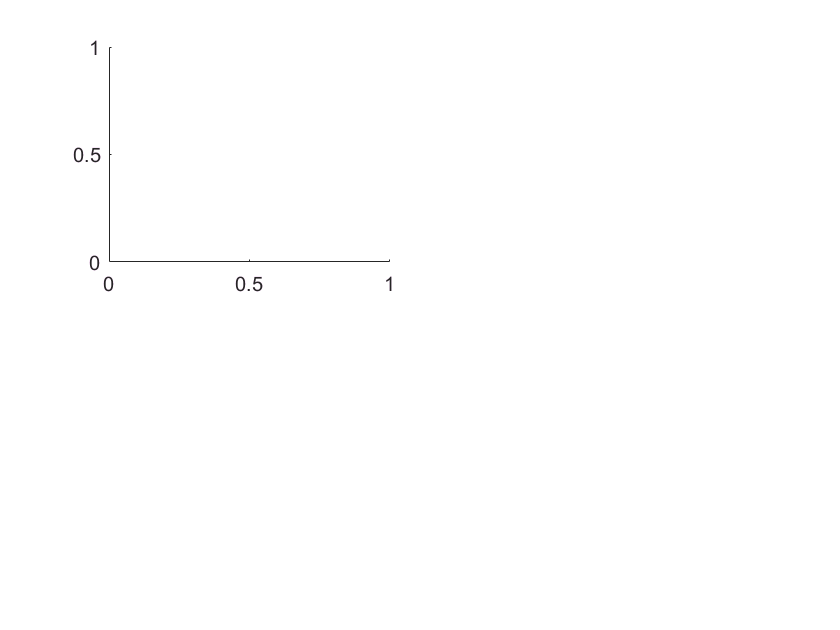

clear allSess_scaled_loBehState_CRF
clear allSess_scaled_hiBehState_CRF 

global run_or_pup
if run_or_pup == 'run'
    global lighter_blue
    loStateLineColor = lighter_blue;
    global orange
    hiStateLineColor = orange;
end 

global run_or_pup
if run_or_pup == 'pup'
    global light_red
    loStateLineColor = light_red;
    global pea_green
    hiStateLineColor = pea_green;
end 

for n = 1:nGroup
    
    figure
    %clear titleText
    %titleText = 'CRF: locomotion';
    %suptitle(sprintf('%s \n',titleText))

    %titleText = 'CRF: '; % making char variables for sprintf/title later
    %subjName = groupSubjName{1}; % will be same name if w/in mouse analysis...
    %date = groupDate{1};
    %suptitle(sprintf('%s',titleText,subjName)); % date, 

    
    for d = durat

        global visArea
        for i = 1:4

            subplot(2,2,i) 

            % take CRF for nth session, for ith point, lo beh state
            %loBehState_meanDthCRFacrossSess = mean(loBehState_allSessAllPtsAllDurs_CRF(d,:,i,n),4);
            loBehState_NthDthCRFSess = loBehState_allSessAllPtsAllDurs_CRF(d,:,i,n);
            % Here's how to get STD of this: 
            % std(squeeze(loBehState_allSessAllPtsAllDurs_CRF(d,:,i,:))',1)

            % max of dth ith CRF
            clear maxOfCRF
            maxOfCRF = max(loBehState_NthDthCRFSess);

            % scale the CRF to it's max
            scaled_loBehState_NthDthCRFSess = loBehState_NthDthCRFSess/maxOfCRF;

            % COLLLECT scaled CRF for each session (to get st err later)
            allSess_scaled_loBehState_CRF(n,:) = scaled_loBehState_NthDthCRFSess;

            % get stdev across sessions
            stdErr_allSess_scaled_loBehState_CRF = std(allSess_scaled_loBehState_CRF)/sqrt(size(loBehState_allSessAllPtsAllDurs_CRF,4));
            %loBehState_stdErrOverSess = std(squeeze(loBehState_allSessAllPtsAllDurs_CRF(d,:,i,:))')/sqrt(size(loBehState_allSessAllPtsAllDurs_CRF,4));
            % stderr across mice
            %global numMice
            %loBehState_stdErrOverSess = std(squeeze(scaled_loBehState_meanDthCRFacrossSess(d,:,i,:))')/sqrt(numMice); 
            %loBehState_stdErrOverSess = std(squeeze(loBehState_allSessAllPtsAllDurs_CRF(d,:,i,:))'); 

            %plot(x_axis,scaled_loBehState_meanDthCRFacrossSess,'color',loStateLineColor,'lineWidth',2,'MarkerSize',3) 
            %errorbar(x_axis,scaled_loBehState_NthDthCRFSess,loBehState_stdErrOverSess,'color',loStateLineColor,'lineWidth',2,'MarkerSize',3) 
            %plot(x_axis,scaled_loBehState_NthDthCRFSess,'color',loStateLineColor,'lineWidth',2,'MarkerSize',3) 
            error(x_axis,scaled_loBehState_NthDthCRFSess,stdErr_allSess_scaled_loBehState_CRF,'color',loStateLineColor,'lineWidth',2,'MarkerSize',3) 
            
    %         if nGroup == 1
    %             
    %             plot(x_axis,loBehState_meanDthCRFacrossSess,'-b','lineWidth',1,'MarkerSize',3) 
    %         
    %         else 
    %             
    %             % plot for lo beh state
    %             errorbar(x_axis,loBehState_meanDthCRFacrossSess,loBehState_stdErrOverSess,'-b','lineWidth',1,'MarkerSize',3) 
    %         
    %         end 

            hold on 

            % take mean across sessions, for ith point, hi beh state
            %hiBehState_meanDthCRFacrossSess = mean(hiBehState_allSessAllPtsAllDurs_CRF(d,:,i,:),4);
            hiBehState_NthDthCRFSess = hiBehState_allSessAllPtsAllDurs_CRF(d,:,i,n);

            
            % max of dth ith CRF
            clear maxOfCRF
            maxOfCRF = max(hiBehState_NthDthCRFSess);

            % scale the CRF to it's max
            scaled_hiBehState_NthDthCRFSess = hiBehState_NthDthCRFSess/maxOfCRF;
            
            % COLLECT scaled CRF for each session (to get st err later)
            allSess_scaled_hiBehState_CRF(n,:) = scaled_hiBehState_NthDthCRFSess;

    %        % get stderr across sessions
             stdErr_allSess_scaled_hiBehState_CRF = std(allSess_scaled_hiBehState_CRF)/sqrt(size(hiBehState_allSessAllPtsAllDurs_CRF,4));
    %        %hiBehState_stdErrOverSess = std(squeeze(hiBehState_allSessAllPtsAllDurs_CRF(d,:,i,:))')/sqrt(size(hiBehState_allSessAllPtsAllDurs_CRF,4)); 
    %        % stderr across mice
             %global numMice
             %hiBehState_stdErrOverSess = std(squeeze(scaled_hiBehState_NthDthCRFSess(d,:,i,:))')/sqrt(numMice); 

            %plot(x_axis,scaled_hiBehState_meanDthCRFacrossSess,'color',hiStateLineColor,'LineWidth',2,'MarkerSize',3) 
            %errorbar(x_axis,scaled_hiBehState_NthDthCRFSess,hiBehState_stdErrOverSess,'color',hiStateLineColor,'lineWidth',2,'MarkerSize',3) 
            %plot(x_axis,scaled_hiBehState_NthDthCRFSess,'color',hiStateLineColor,'lineWidth',2,'MarkerSize',3) 
            error(x_axis,scaled_hiBehState_NthDthCRFSess,stdErr_allSess_scaled_hiBehState_CRF,'color',hiStateLineColor,'lineWidth',2,'MarkerSize',3)
            %plot(x_axis,scaled_loBehState_meanDthCRFacrossSess,'color',hiStateLineColor,'lineWidth',2,'MarkerSize',3)   

    %           if nGroup == 1
    %             
    %             plot(x_axis,hiBehState_meanDthCRFacrossSess,'-r','lineWidth',1,'MarkerSize',3) 
    %             
    %         
    %         else 
    %             
    %             % plot for hi beh state
    %             errorbar(x_axis,hiBehState_meanDthCRFacrossSess,hiBehState_stdErrOverSess,'-r','lineWidth',1,'MarkerSize',3) 
    %             
    %         
    %         end

            title(reigons{i})

            ylim(yLimit) 
            xlim(xLimit)

            ylabel('dF/F')
            xlabel('contrast (%)')

            clear xt
            xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
            set(gca,'xtick',1:7); 
            set(gca,'xticklabel',xt);

    %         yt = [-0.01 0 0.02 0.04 0.06 0.08 0.1];
    %         set(gca,'YTick',yt)

            %legend(stateLegend,'Location','northwest')

        end % i

    end % d

end % n

% USE THIS TO SCALE CRFs each SESS

clear allSess_scaled_loBehState_CRF
clear allSess_scaled_hiBehState_CRF 

for n = 1:nGroup
    
    for d = durat

        global visArea
        for i = 1:4
            
            % LO Beh State

            % take CRF for nth session, for ith point, lo beh state
            loBehState_NthDthCRFSess = loBehState_allSessAllPtsAllDurs_CRF(d,:,i,n);

            % max of dth ith CRF
            clear maxOfCRF
            maxOfCRF = max(loBehState_NthDthCRFSess);

            % scale the CRF to it's max
            scaled_loBehState_NthDthCRFSess = loBehState_NthDthCRFSess/maxOfCRF;

            % COLLLECT scaled CRF for each session (to get st err later)
            allSess_scaled_loBehState_CRF(n,:) = scaled_loBehState_NthDthCRFSess;
         
            
            % HI Beh State

            % take CRF for nth session, for ith point, hi beh state
            hiBehState_NthDthCRFSess = hiBehState_allSessAllPtsAllDurs_CRF(d,:,i,n);
 
            % max of dth ith CRF
            clear maxOfCRF
            maxOfCRF = max(hiBehState_NthDthCRFSess);

            % scale the CRF to it's max
            scaled_hiBehState_NthDthCRFSess = hiBehState_NthDthCRFSess/maxOfCRF;
            
            % COLLECT scaled CRF for each session (to get st err later)
            allSess_scaled_hiBehState_CRF(n,:) = scaled_hiBehState_NthDthCRFSess;

            
        end % i

    end % d

end % n


size(allSess_scaled_loBehState_CRF)

ans =     21     7


size(allSess_scaled_hiBehState_CRF)

ans =     21     7


% get stdev across sessions
stdErr_allSess_scaled_loBehState_CRF = std(allSess_scaled_loBehState_CRF)/sqrt(size(loBehState_allSessAllPtsAllDurs_CRF,4))

stdErr_allSess_scaled_loBehState_CRF =     0.0167    0.0208    0.0322    0.0380    0.0312    0.0271         0


stdErr_allSess_scaled_hiBehState_CRF = std(allSess_scaled_hiBehState_CRF)/sqrt(size(hiBehState_allSessAllPtsAllDurs_CRF,4))      

stdErr_allSess_scaled_hiBehState_CRF =     0.0097    0.0072    0.0175    0.0150    0.0166    0.0135         0


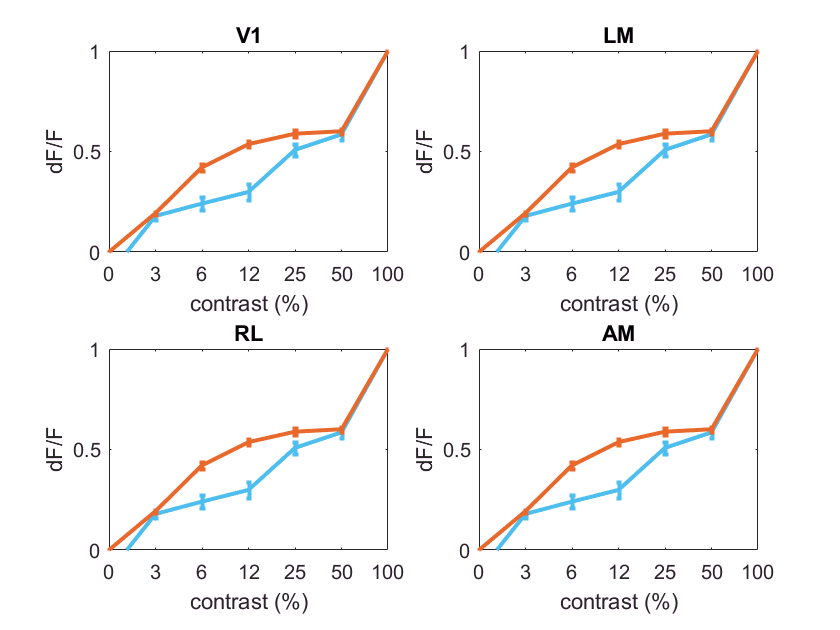

% PLLT w/ERROR BARS

global run_or_pup
if run_or_pup == 'run'
    global lighter_blue
    loStateLineColor = lighter_blue;
    global orange
    hiStateLineColor = orange;
end 

global run_or_pup
if run_or_pup == 'pup'
    global light_red
    loStateLineColor = light_red;
    global pea_green
    hiStateLineColor = pea_green;
end 

figure
%clear titleText
%titleText = 'CRF: locomotion';
%suptitle(sprintf('%s \n',titleText))

%titleText = 'CRF: '; % making char variables for sprintf/title later
%subjName = groupSubjName{1}; % will be same name if w/in mouse analysis...
%date = groupDate{1};
%suptitle(sprintf('%s',titleText,subjName)); % date, 

for d = durat
    
    for i = visArea
        
        subplot(2,2,i) 

        %plot(x_axis,scaled_loBehState_meanDthCRFacrossSess,'color',loStateLineColor,'lineWidth',2,'MarkerSize',3) 
        %errorbar(x_axis,scaled_loBehState_NthDthCRFSess,loBehState_stdErrOverSess,'color',loStateLineColor,'lineWidth',2,'MarkerSize',3) 
        %plot(x_axis,scaled_loBehState_NthDthCRFSess,'color',loStateLineColor,'lineWidth',2,'MarkerSize',3) 
        errorbar(x_axis,scaled_loBehState_NthDthCRFSess,stdErr_allSess_scaled_loBehState_CRF,'color',loStateLineColor,'lineWidth',2,'MarkerSize',3) 
            
    %         if nGroup == 1
    %             
    %             plot(x_axis,loBehState_meanDthCRFacrossSess,'-b','lineWidth',1,'MarkerSize',3) 
    %         
    %         else 
    %             
    %             % plot for lo beh state
    %             errorbar(x_axis,loBehState_meanDthCRFacrossSess,loBehState_stdErrOverSess,'-b','lineWidth',1,'MarkerSize',3) 
    %         
    %         end 

    
        hold on 

        %plot(x_axis,scaled_hiBehState_meanDthCRFacrossSess,'color',hiStateLineColor,'LineWidth',2,'MarkerSize',3) 
        %errorbar(x_axis,scaled_hiBehState_NthDthCRFSess,hiBehState_stdErrOverSess,'color',hiStateLineColor,'lineWidth',2,'MarkerSize',3) 
        %plot(x_axis,scaled_hiBehState_NthDthCRFSess,'color',hiStateLineColor,'lineWidth',2,'MarkerSize',3) 
        errorbar(x_axis,scaled_hiBehState_NthDthCRFSess,stdErr_allSess_scaled_hiBehState_CRF,'color',hiStateLineColor,'lineWidth',2,'MarkerSize',3)
        %plot(x_axis,scaled_loBehState_meanDthCRFacrossSess,'color',hiStateLineColor,'lineWidth',2,'MarkerSize',3)   

    %           if nGroup == 1
    %             
    %             plot(x_axis,hiBehState_meanDthCRFacrossSess,'-r','lineWidth',1,'MarkerSize',3) 
    %             
    %         
    %         else 
    %             
    %             % plot for hi beh state
    %             errorbar(x_axis,hiBehState_meanDthCRFacrossSess,hiBehState_stdErrOverSess,'-r','lineWidth',1,'MarkerSize',3) 
    %             
    %         
    %         end

        
        title(reigons{i})

        ylim(yLimit) 
        xlim(xLimit)

        ylabel('dF/F')
        xlabel('contrast (%)')

        clear xt
        xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
        set(gca,'xtick',1:7); 
        set(gca,'xticklabel',xt);

%         yt = [-0.01 0 0.02 0.04 0.06 0.08 0.1];
%         set(gca,'YTick',yt)

        %legend(stateLegend,'Location','northwest')
            
    end
    
end